# Problem Set 1

**Submission: **submit a single PDF file to Canvas

**Due: **1/25/2022

**Questions: **Please post all questions to Piazza

This problem set is to familiarize yourself with MATLAB, the Singular Value Decomposition (SVD), and working with real data. You are encouraged to collaborate on the problem sets, but you must include the names and uniqnames of anyone you work with in your submission. The starter code is intended to provide a baseline introduction to the material, and you are encouraged to write additional code to explore the concepts. Please include any plots generated with the code in your written solutions.

**References:**

- [Mathematical Writing: A Primer](https://drive.google.com/file/d/1n-7fnTi3rEKX61jKllVVrBg-snrFhp3E/view?ts=63214e3b)

- [MATLAB Basic Functions Reference](https://www.google.com/url?q=https%3A%2F%2Fwww.mathworks.com%2Fcontent%2Fdam%2Fmathworks%2Ffact-sheet%2Fmatlab-basic-functions-reference.pdf&sa=D&sntz=1&usg=AOvVaw0Srty3yRZ16keZTPoYGuFB)

- [MATLAB Tutorial](https://drive.google.com/file/d/1VcDPSiITW-7hRah3xPNwIBXSnmkcp17w/view?usp=sharing)

- [Singular Value Decompositio Notes Set](https://drive.google.com/file/d/1g3WZdAYV2p__pjuyX1-E4eTGfV7Kg3TE/view?usp=share_link)

## Problem 1

Familiarize yourself with the SVD and eigenvalues and eigenvectors by working through this problem. Part A may be worked by hand, and parts B and C you can use the `svd() `and `eig()` commands.

- svd: [https://www.mathworks.com/help/matlab/ref/double.svd.html](https://www.mathworks.com/help/matlab/ref/double.svd.html)

- eig: [https://www.mathworks.com/help/matlab/ref/eig.html](https://www.mathworks.com/help/matlab/ref/eig.html)

A = [1 1 0; 0 1 1]

A =      1     1     0
     0     1     1


B = A'*A;
[V, D] = eig(B)

V =     0.5774   -0.7071    0.4082
   -0.5774   -0.0000    0.8165
    0.5774    0.7071    0.4082


D =     0.0000         0         0
         0    1.0000         0
         0         0    3.0000


[U, S, Vt] = svd(A)

U =    -0.7071    0.7071
   -0.7071   -0.7071


S =     1.7321         0         0
         0    1.0000         0


Vt =    -0.4082    0.7071    0.5774
   -0.8165   -0.0000   -0.5774
   -0.4082   -0.7071    0.5774


## Problem 2

Analyze the responses to the class introduction survey. This section introduces loading data into MATLAB and some additional basic commands.

### Part A

% Load the dataset as a MATLAB table
data = readtable('MATH 547 Introductions.csv', 'VariableNamingRule',"preserve");

% print the size of the table to the console
s = size(data);
disp(s)

   146    28



% Convert data table to a MATLAB matrix
D = data; % Make a copy of the original raw data
% Remove columns with text instead of numeric values
D.('What do you plan to do after your program?') = [];
D.('Choose the best description of your background') = [];
D.('Choose the option that best describes you') = [];
D.('Please list any topics not covered in the list above that you w') = [];

% Extract data to a matrix A
A = D{:,:};

% Get rank of A
r = rank(A);    % Get Rank
disp(r)         % Display rank to the screen

    24



### Part B

% Extract column of data about responses to SVD Excitement
SVD_excitement = data.('In this section please indicate how excited you are by the f_2'); % f_2 is SVD;
% Calculate and display the mean value
disp(mean(SVD_excitement))

    3.5890



disp(mean(data.('In this section please indicate how excited you are by the f_4'))); % f_4 is machine learning

    3.7603



disp(mean(data.('In this section please indicate how excited you are by the f_11'))); % f_11 is Real data

    3.9521



disp(mean(data.('In this section please indicate how excited you are by the f_12'))); % f_12 is Programming/MATLAB

    3.2397



### Part C

Generate a plot describing the relationship between students interest and their current skills you may make any type of plot you want. Some helpful commands may be `plot(), histogram(), scatter(). `You should write this section of code yourself.

### Part D

Compute the SVD of the data matrix A

% take the SVD of the data
[u, s, v] = svd(A);

size(u)
size(s)
size(v)

### Part E

Plot a scree plot of the data. How does this impact your perception of the rank of A?

% generate a scree plot
close all; 


ans =     66    66


S = diag(s);

ans =     66    23


% scatter(S, 1:length(S))

ans =     23    23


semilogy(S,'k','LineWidth',1.5);
hold on;
title("Singular Values of A");
ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;

semilogy(S,'or','LineWidth',1.5);
hold off;

### Part F

Compute AAt and AtA. How do their sizes compare, and what does each new matrix represent? How do you interpret the visualizations below?

AtA = A' * A;
size(AtA)
AAt = A * A';
size(AAt)
imagesc(AtA)
imagesc(AAt)

### Part G

Compute the SVD of these new matrices. How do the singular values of each compare to one another? How do these values compare to the singular values of the original data? You can make these comparisons by utilizng the plot below or based on looking at the values of each vector.

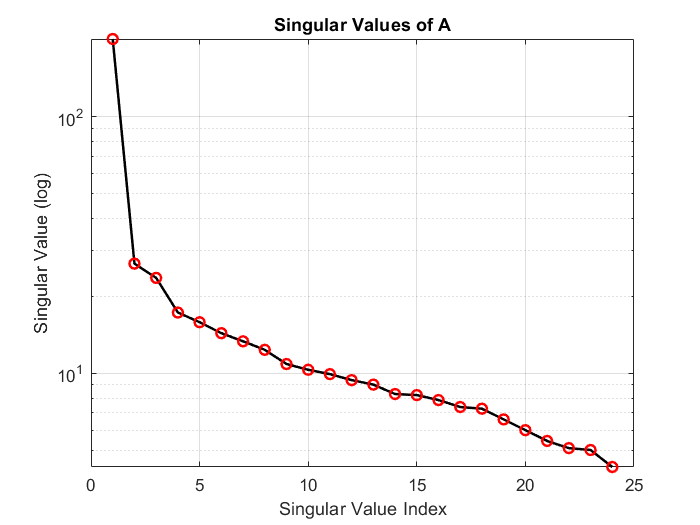

[u1, s1, v1] = svd(AtA);
[u2, s2, v2] = svd(AAt);


% generate a scree plot
close all; 

S = diag(s1);

ans =     24    24



semilogy(S,'k','LineWidth',1.5);

ans =    146   146


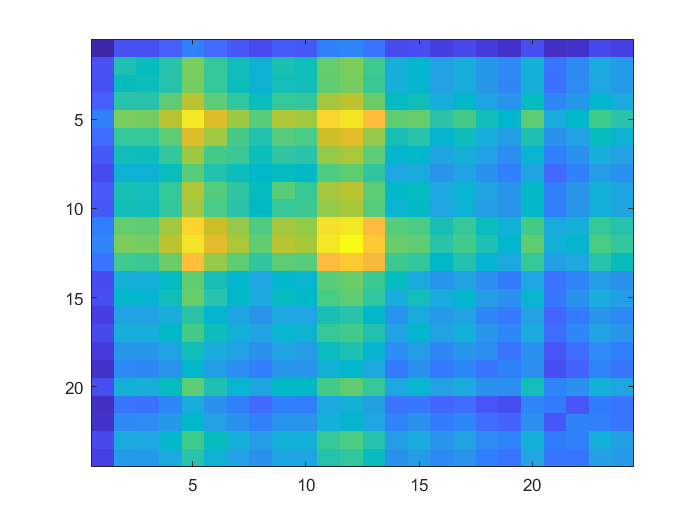

hold on;

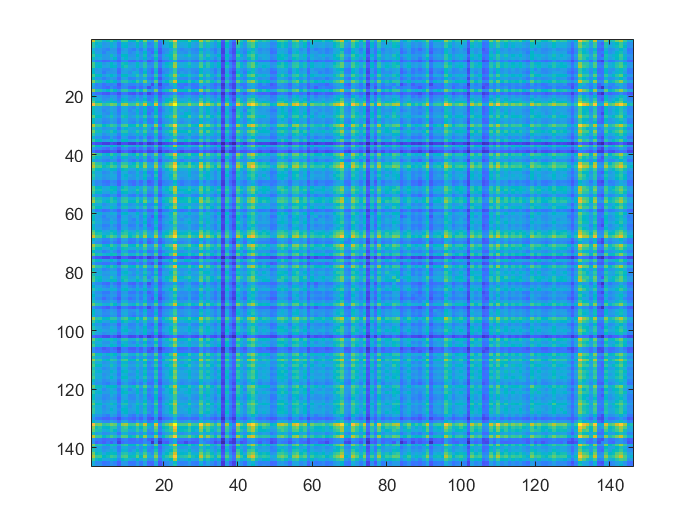

title("Singular Values of A^T A");

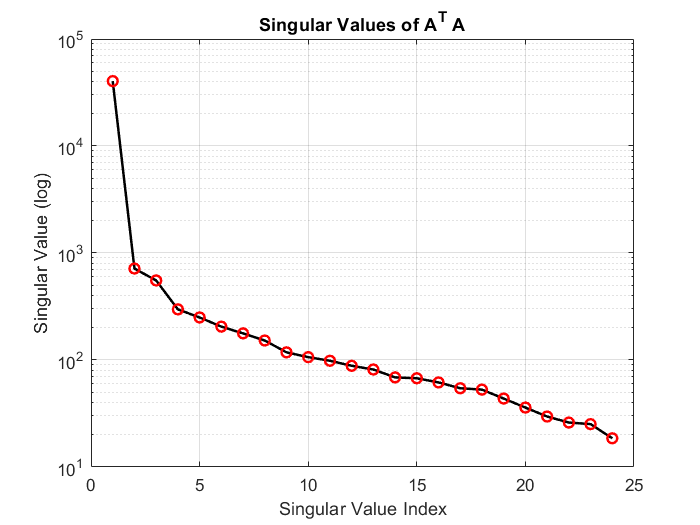

ylabel('Singular Value (log)');
xlabel('Singular Value Index');
grid on;

semilogy(S,'or','LineWidth',1.5);
hold off;